nh_nsc = dicomread("C0000001.dcm");
yh_nsc = dicomread("C0000002.dcm");
nh_ysc = dicomread("C0000003.dcm");
gain_vol = dicomread("C0000004.dcm");
swe_vol = dicomread("C0000006.dcm");
swe_im = dicomread("I0000005.dcm");

sz_nn = size(nh_nsc);
sz_yn = size(yh_nsc);
sz_ny = size(nh_ysc);
sz_gain = size(gain_vol);
sz_swe = size(swe_vol);
sz_im = size(swe_im);

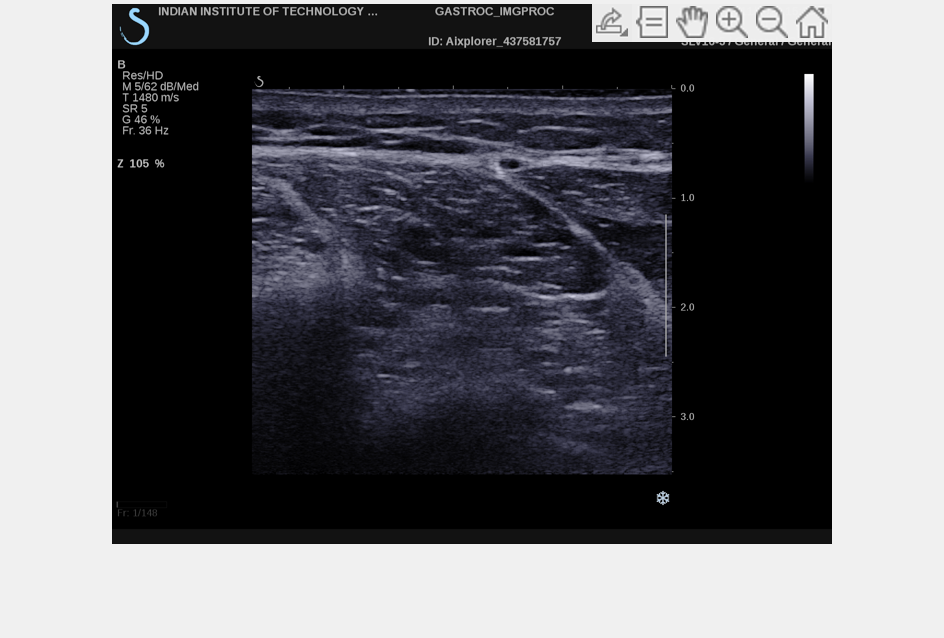

crp1 = 385×412×3 uint8 array
crp1(:,:,1) =

    68    76    76    68    57    44    35    33    33    38    43    38    39    43    38    33    39    46    44    39    38    44    47    46    44    41    35    26    30    39    46    47    49    49    35    30    26    26    30    36    36    35    29    24    26    32    38    39    35    29    29    33    36    39    41    39    38    35    32    29    29    33    38    38    32    33    38    38    38    39    39    41    41    39    41    41    39    39    44    44    44    47    51    51    47    44    46    52    41    36    39    43    43    43    41    39    41    41    39    39    44    47    46    46    44    41    38    35    35    33    33    33    35    36    36    32    26    23    26    29    30    30    32    33    32    32    33    38    43    44    44    43    44    49    47    51    51    51    60    64    64    54    54    44    38    39    36    33    32    44    79   104   119   127   129   126   119   106    76  

nh_nsc_crd =   144.5100   85.5100  411.9800  384.9800


[crp1, nh_nsc_crd] = imcrop(nh_nsc(:,:,:,1))

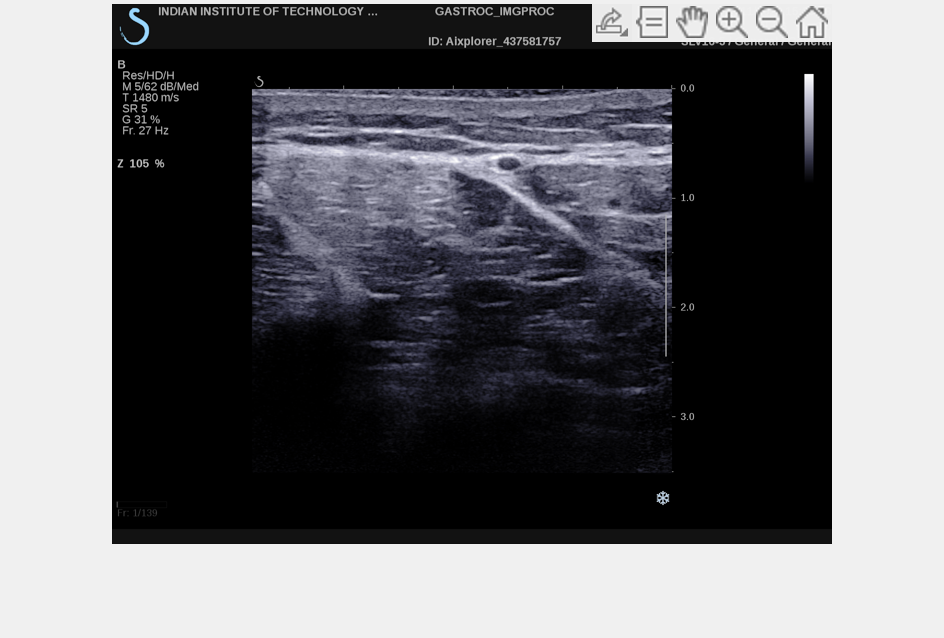

crp2 = 367×412×3 uint8 array
crp2(:,:,1) =

     0     0     0     0    11    13     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    19    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    96    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    91    19     0     0     0     0     0     0     0     0     0     0     0     0     0  

yh_nsc_crd =   142.5100   83.5100  411.9800  366.9800


[crp2, yh_nsc_crd] = imcrop(yh_nsc(:,:,:,1))

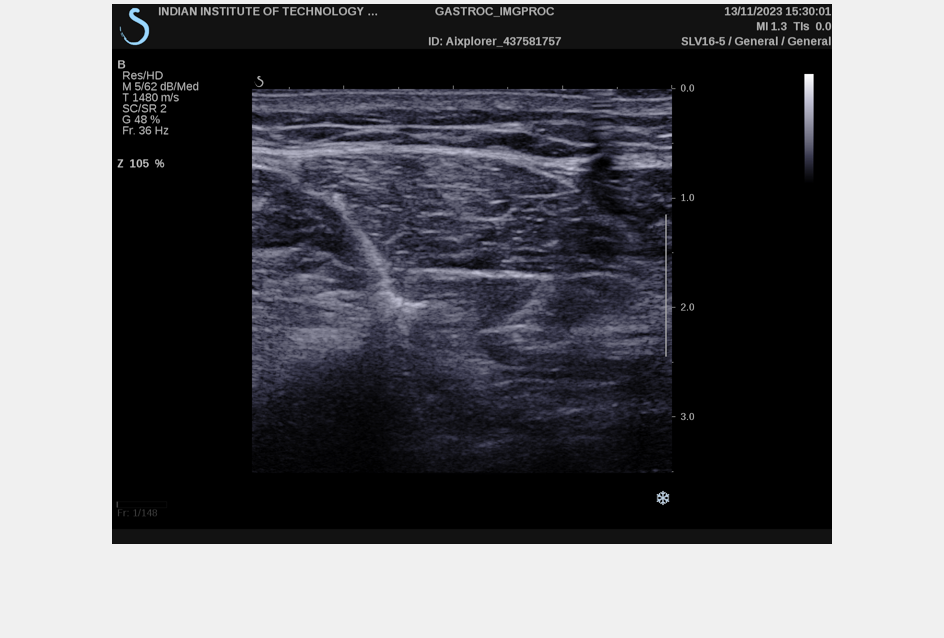

crp3 = 365×408×3 uint8 array
crp3(:,:,1) =

    56    54    44    46    52    52    46    44    46    43    47    51    57    54    46    39    36    36    35    39    51    62    62    59    57    59    57    54    51    54    56    52    44    47    57    70    60    54    44    39    41    39    41    46    46    51    52    52    52    44    39    46    57    64    59    47    35    32    41    52    49    44    41    41    49    49    43    52    79    92    92    80    71    64    56    60    71    65    52    62    74    70    59    57    59    56    52    51    52    68    71    77    77    70    59    52    60    73    80    83    77    67    62    59    64    62    60    62    62    57    49    43    46    47    51    54    54    59    57    46    41    43    46    41    41    46    44    49    56    52    46    44    41    39    47    60    70    82    94    99   102    99    94    90    94    87    79    74    86    95    99    97   101   102    97    97    99    96    95  

nh_ysc_crd =   142.5100   85.5100  407.9800  364.9800


[crp3, nh_ysc_crd] = imcrop(nh_ysc(:,:,:,1))

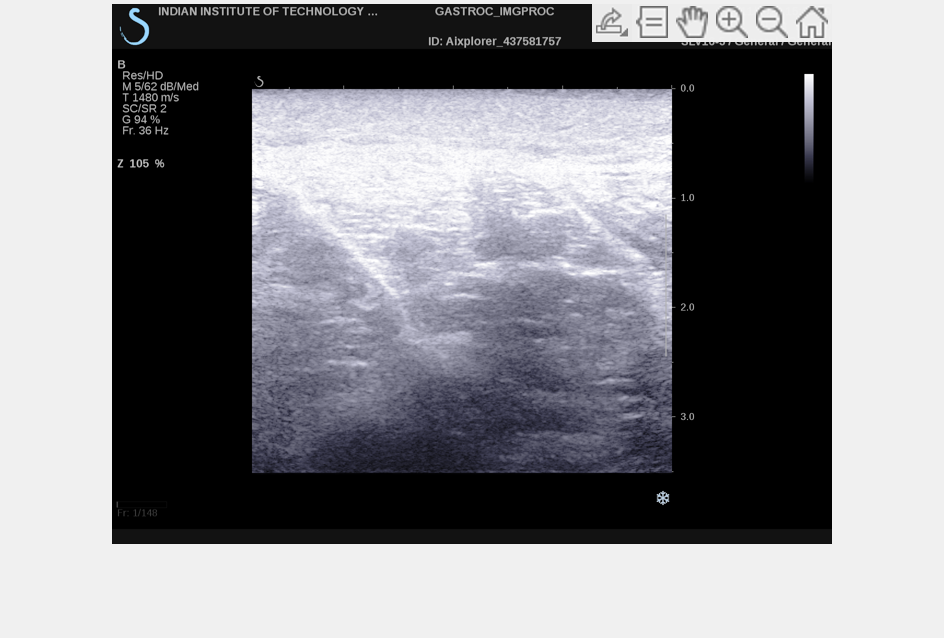

crp4 = 385×410×3 uint8 array
crp4(:,:,1) =

     0     0    11    13     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    19    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    96    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    90    18     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

gain_crd =   144.5100   83.5100  409.9800  384.9800


[crp4, gain_crd] = imcrop(gain_vol(:,:,:,1))

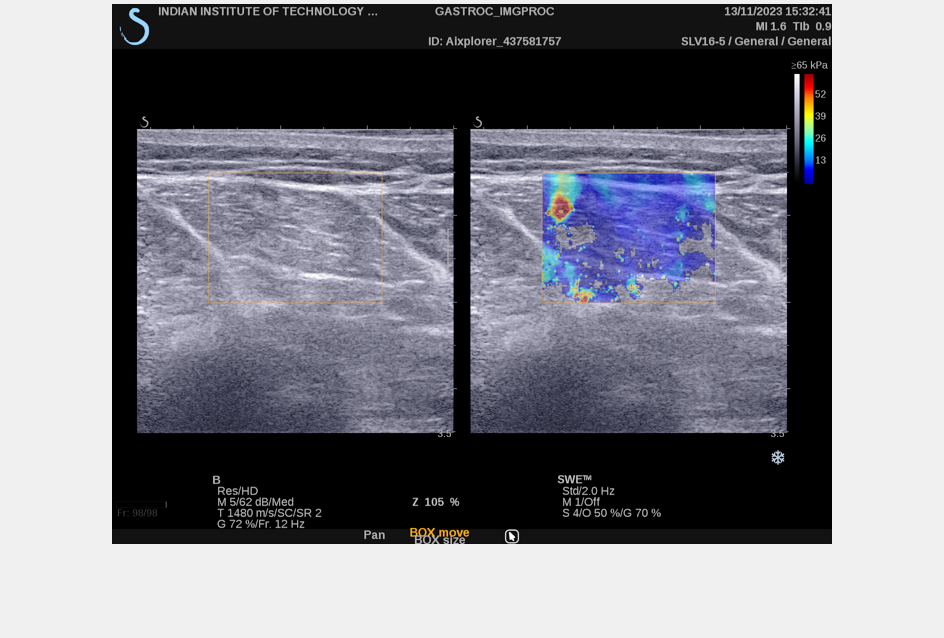

crp5 = 309×308×3 uint8 array
crp5(:,:,1) =

     0     6    68   100    87    22     0     0     0    90    18     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    20    96     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    19    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    96    19     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

swe_crd =   362.5100  123.5100  307.9800  308.9800


[crp5, swe_crd] = imcrop(swe_vol(:,:,:,1))

xref1 = floor([nh_nsc_crd(1),nh_nsc_crd(1)+nh_nsc_crd(3)])

xref1 =    144   556


yref1 = floor([nh_nsc_crd(2),nh_nsc_crd(2)+nh_nsc_crd(4)])

yref1 =     85   470


xref2 = floor([yh_nsc_crd(1),yh_nsc_crd(1)+yh_nsc_crd(3)])

xref2 =    142   554


yref2 = floor([yh_nsc_crd(2),yh_nsc_crd(2)+yh_nsc_crd(4)])

yref2 =     83   450


xref3 = floor([nh_ysc_crd(1),nh_ysc_crd(1)+nh_ysc_crd(3)])

xref3 =    142   550


yref3 = floor([nh_ysc_crd(2),nh_ysc_crd(2)+nh_ysc_crd(4)])

yref3 =     85   450


xref4 = floor([gain_crd(1),gain_crd(1)+gain_crd(3)])

xref4 =    144   554


yref4 = floor([gain_crd(2),gain_crd(2)+gain_crd(4)])

yref4 =     83   468


xref5 = floor([swe_crd(1),swe_crd(1)+swe_crd(3)])

xref5 =    362   670


yref5 = floor([swe_crd(2),swe_crd(2)+swe_crd(4)])

yref5 =    123   432


vol_nn = squeeze(nh_nsc(yref1(1):yref1(2),xref1(1):xref1(2),1,:))

vol_nn = 386×413×148 uint8 array
vol_nn(:,:,1) =

     2     2     2     0     0     1     1     1     1     1     1     2     2     1     1     1     1     1     2     2     1     1     2     2     2     2     1     1     1     1     1     2     0    23    94     0     1     1     2     2     2     2     2     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     0    92    22     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     1     1     1     0    94    22     0     1     1     1     1     1     3     6     7     7     8     8     7  

vol_yn = squeeze(yh_nsc(yref2(1):yref2(2),xref2(1):xref2(2),1,:))

vol_yn = 368×413×139 uint8 array
vol_yn(:,:,1) =

     0     0     0    16    95   123   134   135    59     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   101    23     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     5     1     0     0     0     0     0     0     0     0     0     0     0  

vol_ny = squeeze(nh_ysc(yref3(1):yref3(2),xref3(1):xref3(2),1,:))

vol_ny = 366×409×148 uint8 array
vol_ny(:,:,1) =

     3     3     2     2     1     0     0     1     2     2     2     2     2     2     2     2     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     2     2     1     0    22    94     0     1     1     1     1     1     1     1     2     1     1     1     1     1     1     2     2     2     2     2     1     1     1     2     2     1     1     1     1     2     2     3     3     5     3     3     2     1     1     2     2     2     1     1     2     2     2     2     2     2     2     1     0    92    22     1     5     5     5     5     5     5     5     5     5     3     2     2     2     2     1     2     2     1     1     1     2     2     2     2     1     1     1     1     1     1     2     2     1     1     1     1     2     1     1     1     1     1     1     2     2     3     5     6     6     6     6     0    97    26     2     3     5     5     5     5     5     6     7     7     7  

vol_gain = squeeze(gain_vol(yref4(1):yref4(2),xref4(1):xref4(2),1,:))

vol_gain = 386×411×148 uint8 array
vol_gain(:,:,1) =

     0    16    95   123   134   135    59     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   101    23     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     5     1     0     0     0     0     0     0     0     0     0     0     0     0    

vol_swe = swe_vol(yref5(1):yref5(2),xref5(1):xref5(2),:,:)

vol_swe = 310×309×3×98 uint8 array
vol_swe(:,:,1,1) =

     0    20    99    76    79   109   156    79     0     0     5     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    23   101     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   101    23     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

bw = rgb2gray(vol_swe(:,:,:,1))

bw = 308×305 uint8 matrix
     8     5     2     3     8    10     9     2   100    29     6     7     6     7     7     6     5     5     6     8     7     7     7     8     8     8     7     6     6     6     6     6     6     3     7    11    14    15    14    11     6     6     7     6     7     6     7     7     7     8
   167   168   162   159   166   166   164   163   164   160   157   151   144   143   144   135   128   141   150   148   140   140   139   151   155   146   134   127   119   124   127   134   141   140   154   176   189   193   184   162   116   124   144   134   135   140   145   142   142   154
   182   177   170   168   170   171   173   179   181   178   177   180   183   184   185   177   169   173   161   156   164   165   164   172   172   160   152   159   162   160   156   157   170   177   177   177   177   176   170   160   140   156   172   166   156   159   168   165   158   168
   154   144   128   130   139   139   140   144   148   149   148   14

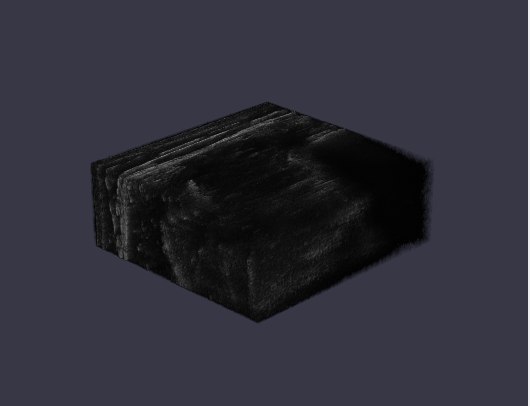

imshow(bw)

im = squeeze(vol_nn(:,100,:))

im = 392×148 uint8 matrix
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    41    41    41    41    41    41    38    38    36    41    39    43    43    41    38    33    32    26    23    22    23    23    23    22    22    19    18    16    15    15    14    13    13    13    11    11    10    10    11    11    10    10     9     9     8     9     8     7     7     7
    52    54    56    47    46    44    46    47    51    52    47    47    49    51    51    52    56    52    49    46    49    52    54    54    52    51    51    47    47    47    49    49    47    46    44    43    41    36    41    41    43    39    36    36    36    41    41    36    35    33
    22    26    27    24    19    18    20    24    30    30    27    2

im1 = squeeze(vol_nn(100,:,:))

im1 = 407×148 uint8 matrix
   160   165   166   125   113   109   128   135   135   147   148   148   125   113   110    68    52    46    47    47    47    64    70    73    57    51    49    38    32    30    32    35    35    47    54    57    64    68    70    57    52    51    57    60    62    79    80    80    47    33
   147   155   156   117   103    99   116   126   128   140   142   142   126   114   111    67    49    41    51    56    57    73    77    79    60    54    51    36    30    26    20    19    18    35    47    52    67    74    76    70    67    65    60    60    59    74    76    76    44    32
   127   139   140   102    83    76    97   113   116   125   128   129   121   109   106    70    56    51    59    62    64    68    68    68    59    54    52    43    36    33    33    35    35    32    33    35    64    79    83    86    83    82    65    57    54    65    65    67    51    43
   113   127   130    90    67    57    84   103   108   109   110   1

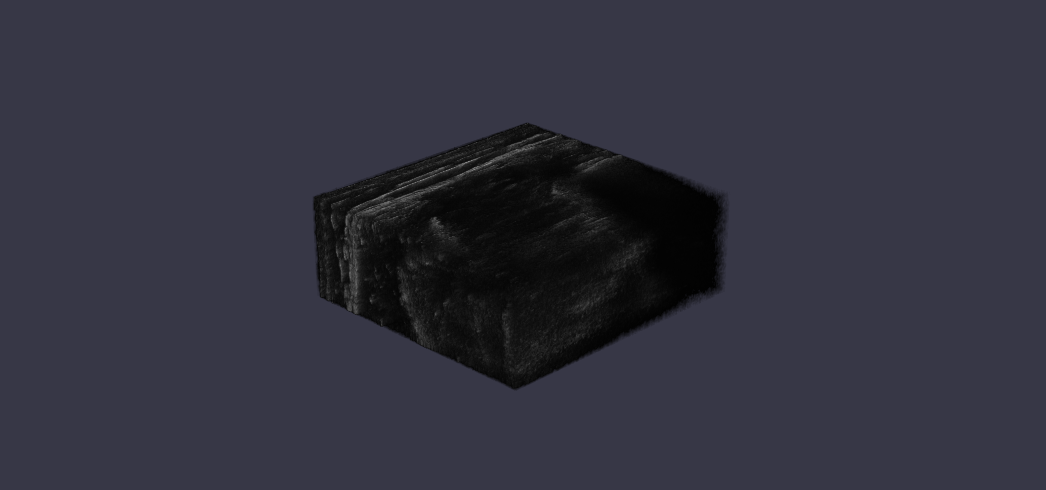

imshowpair(vol_nn(:,:,1), vol_yn(:,:,1),'montage')

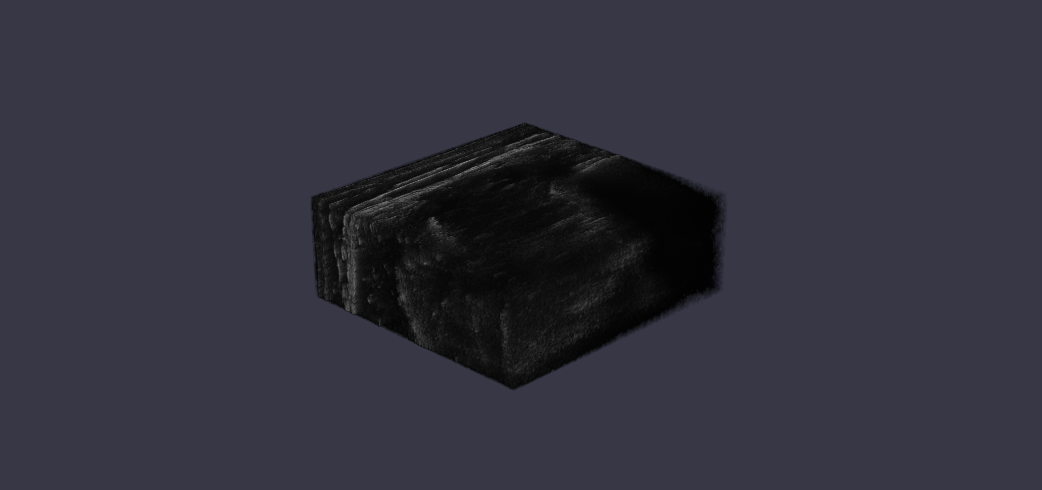

imshowpair(vol_nn(:,:,1), vol_ny(:,:,1),'montage')

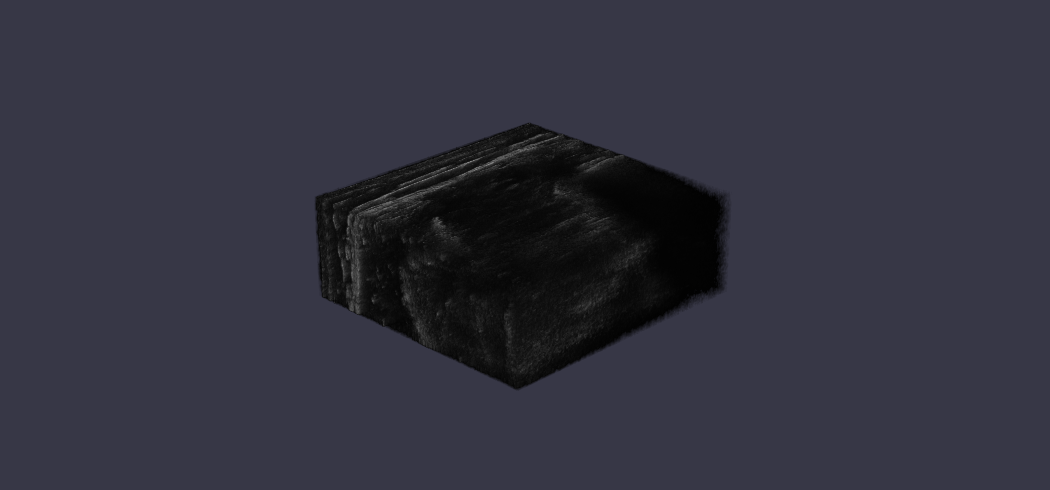

imshowpair(vol_nn(:,:,1), vol_gain(:,:,1),'montage')

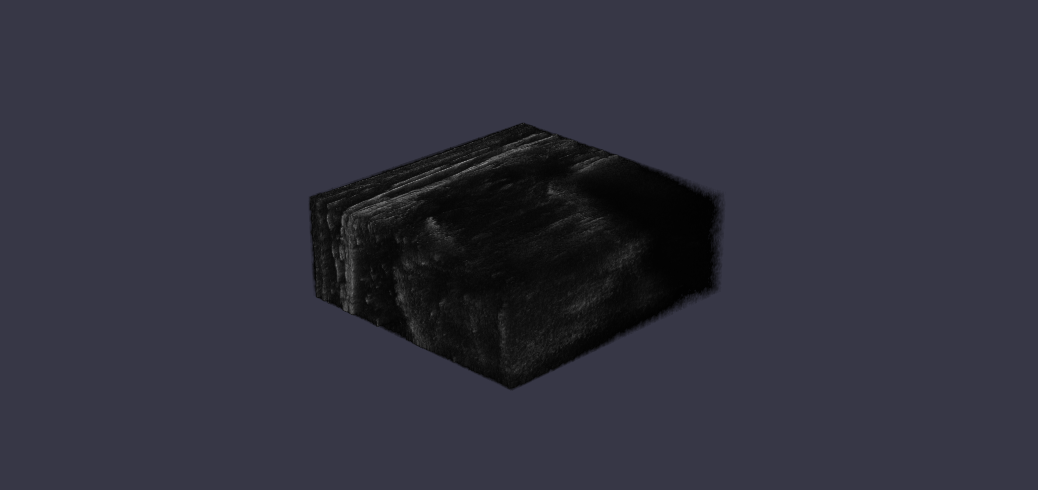


imshowpair(vol_nn(:,:,1), vol_swe(:,:,:,1),'montage')

gain_im = imcrop(vol_gain(:,:,1))


gain_im =

     []



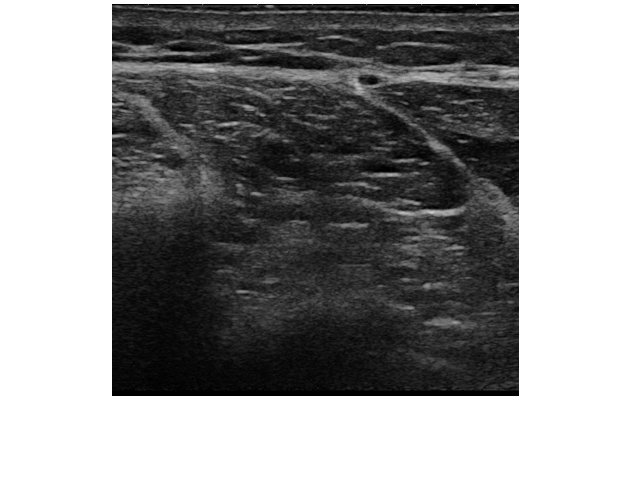


org_im =

     []



org_im = imcrop(vol_nn(:,:,1))

s1 = size(gain_im(:))

s1 =      0     1


s2 = size(org_im(:))

s2 =      0     1


s3 = min(s1,s2)

s3 =      0     1


vec1 = double(gain_im(1:s3))


vec1 =

  1×0 empty double row vector



vec2 = double(org_im(1:s3))


vec2 =

  1×0 empty double row vector



lm = fitlm(vec2,vec1)

lm = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate    SE    tStat    pValue
                   ________    __    _____    ______

    (Intercept)       0        0      NaN      NaN  
    x1                0        0      NaN      NaN  


Number of observations: 0, Error degrees of freedom: 0
R-squared: NaN,  Adjusted R-Squared: NaN
F-statistic vs. constant model: NaN, p-value = NaN

var_model = lm.Coefficients.Estimate

var_model =      0
     0


re_im = (gain_im - var_model(1))/var_model(2)


re_im =

     []



re_wh_im = (vol_gain(:,:,1) - var_model(1))/var_model(2)

re_wh_im = 388×413 uint8 matrix
     0     0     0     0   255   255     0     0     0     0   255   255   255     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0   255   255   255   255   255   255   255   255     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0   255   255   255   255   255   255     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   255   255     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0   255   255   255     

imshow(re_im)

imshow(gain_im)

imshow(org_im)

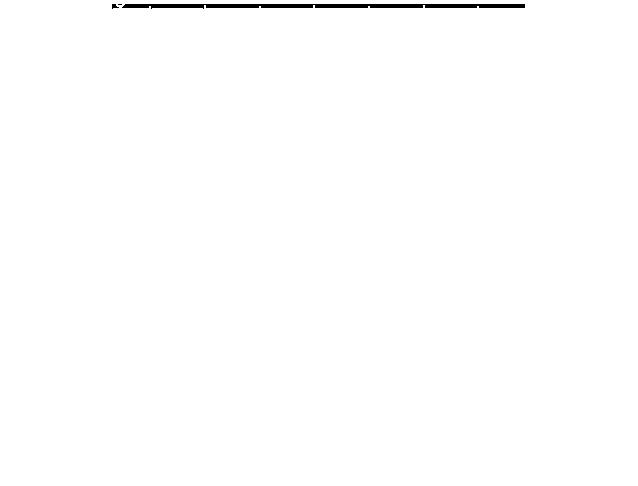

imshow(re_wh_im)

gain_im1 = vol_gain(:,:,1)

gain_im1 = 388×413 uint8 matrix
     0     0     0     0    51    36     0     0     0     0    95   159    13     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     7   100    30     5     6    83   164    74     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0    16    95   123   134   135    59     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     5     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0    11    13     1     

lin_gain = gain_im1-10/1.5

lin_gain = 388×413 uint8 matrix
     0     0     0     0    44    29     0     0     0     0    88   152     6     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0    93    23     0     0    76   157    67     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     9    88   116   127   128    52     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     4     6     0     

imshow(lin_gain)

gamma_gain = imadjust(gain_im1,[],[],3)

gamma_gain = 382×405 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1    15     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    28    22    25    27    22    25    29    26    24    29    33    35    35    41    48    49    47    44    49    49    43    41    32    24    20    23    28    27    32    57    78    84    78    63    44    29    23    22    23    22    27    41    53    54    51    52    46    32    29    32
    29    29    35    40    47    51    54    52    49    51    47    37    48    64    72    70    63    55    55    58    61    57    51    47    43    43    44    41    48    67    73    77    73    63    54    39    35    38    44    54    68    78    82    84    87    87    72    52    42    38
    40    32    27    26    36    42    40    44    55    68   

imshow(gamma_gain)

mus_fas = vol_ny(:,:,1)

mus_fas = 386×415 uint8 matrix
     0     0     0     2     3     3     2     2     1     0     0     1     2     2     2     2     2     2     2     2     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     2     2     1     0    22    94     0     1     1     1     1     1     1     1     2
     0     0     2    43    56    56    54    44    46    52    52    46    44    46    43    47    51    57    54    46    39    36    36    35    39    51    62    62    59    57    59    57    54    51    54    56    52    44    47    57    70    60    54    44    39    41    39    41    46    46
     0     0     2    30    35    33    36    44    60    73    70    60    49    44    46    52    54    49    44    43    39    32    30    39    51    65    73    70    59    52    54    56    54    57    67    67    57    52    60    73    82    80    71    64    62    59    52    47    54    57
     0     0     1    22    16    15    24    38    49    56    59

hp_flt = fspecial('prewitt')

hp_flt =      1     1     1
     0     0     0
    -1    -1    -1


flt_im1 = imfilter(mus_fas,hp_flt)

flt_im1 = 386×415 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    22    62   102   111    77    33     0     0     0     0     0     0     6    11    35    61    71    59    44    37    25     5     0    12    46    68    75    81    88    88    71    55    48    47    37    30    32    50    52    47    25     4     0     0     9    15     6     0
     0     0     0     0     0     0     0     0     8    64    85

imshow(flt_im1)

sz = size(flt_im1)

sz =    386   415


fft_im1 = fftshift(fft2(mus_fas))

fft_im1 = 	1.0e+06 *

   0.0001 + 0.0000i   0.0001 + 0.0001i  -0.0004 - 0.0001i   0.0001 - 0.0001i   0.0001 - 0.0001i  -0.0004 + 0.0001i   0.0001 - 0.0002i  -0.0000 + 0.0004i  -0.0000 + 0.0000i   0.0001 + 0.0002i  -0.0001 - 0.0006i   0.0001 - 0.0002i   0.0004 + 0.0002i  -0.0003 + 0.0001i   0.0002 + 0.0000i  -0.0001 - 0.0002i   0.0000 - 0.0001i   0.0000 - 0.0001i  -0.0004 - 0.0003i  -0.0003 - 0.0002i   0.0001 + 0.0002i   0.0001 + 0.0000i   0.0001 - 0.0001i  -0.0002 - 0.0002i   0.0001 - 0.0001i  -0.0002 + 0.0002i  -0.0003 + 0.0002i   0.0001 - 0.0002i  -0.0002 + 0.0002i   0.0000 + 0.0000i   0.0001 - 0.0001i   0.0002 - 0.0003i   0.0001 - 0.0003i  -0.0005 + 0.0005i  -0.0004 + 0.0002i   0.0004 - 0.0002i  -0.0002 - 0.0003i   0.0000 - 0.0000i   0.0001 - 0.0002i  -0.0003 + 0.0002i   0.0003 + 0.0001i  -0.0000 + 0.0001i   0.0000 + 0.0001i  -0.0000 - 0.0003i  -0.0005 - 0.0003i  -0.0006 - 0.0003i  -0.0002 - 0.0003i  -0.0003 - 0.0001i   0.0001 - 0.0003i  -0.0000 - 0.0001i
  -0.0001 - 0.0000i  -0.000

h =[1.1667    1.6667    1.1667
    1.6667   -1.3334   1.6667
    1.1667    1.6667    1.1667];
x1 = ceil(sz(1)/2) - 2; 

x2 = ceil(sz(2)/2) -2;
D = padarray(h,[x1,x2],1,'both');
fft_im1 = fft_im1(1:sz(1)-1,:)

fft_im1 = 	1.0e+06 *

   0.0001 + 0.0000i   0.0001 + 0.0001i  -0.0004 - 0.0001i   0.0001 - 0.0001i   0.0001 - 0.0001i  -0.0004 + 0.0001i   0.0001 - 0.0002i  -0.0000 + 0.0004i  -0.0000 + 0.0000i   0.0001 + 0.0002i  -0.0001 - 0.0006i   0.0001 - 0.0002i   0.0004 + 0.0002i  -0.0003 + 0.0001i   0.0002 + 0.0000i  -0.0001 - 0.0002i   0.0000 - 0.0001i   0.0000 - 0.0001i  -0.0004 - 0.0003i  -0.0003 - 0.0002i   0.0001 + 0.0002i   0.0001 + 0.0000i   0.0001 - 0.0001i  -0.0002 - 0.0002i   0.0001 - 0.0001i  -0.0002 + 0.0002i  -0.0003 + 0.0002i   0.0001 - 0.0002i  -0.0002 + 0.0002i   0.0000 + 0.0000i   0.0001 - 0.0001i   0.0002 - 0.0003i   0.0001 - 0.0003i  -0.0005 + 0.0005i  -0.0004 + 0.0002i   0.0004 - 0.0002i  -0.0002 - 0.0003i   0.0000 - 0.0000i   0.0001 - 0.0002i  -0.0003 + 0.0002i   0.0003 + 0.0001i  -0.0000 + 0.0001i   0.0000 + 0.0001i  -0.0000 - 0.0003i  -0.0005 - 0.0003i  -0.0006 - 0.0003i  -0.0002 - 0.0003i  -0.0003 - 0.0001i   0.0001 - 0.0003i  -0.0000 - 0.0001i
  -0.0001 - 0.0000i  -0.000

size(D)

ans =    385   415


hp_filtered = D .* fft_im1;
hp_filtered_ifft = ifft2(hp_filtered);
figure('name','hp_filtered')
imagesc(abs(hp_filtered_ifft));
colormap('gray');
colorbar;

mag_spec = log(1 + abs(fft_im1));
imagesc(mag_spec)

plot(abs(fft_im1))

res_im = flt_im1 + mus_fas

res_im = 386×415 uint8 matrix
     0     0     0     2     3     3     2     2     1     0     0     1     2     2     2     2     2     2     2     2     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     2     2     1     0    22    94     0     1     1     1     1     1     1     1     2
     0     0     2    43    56    56    54    44    46    52    52    46    44    46    43    47    51    57    54    46    39    36    36    35    39    51    62    62    59    57    59    57    54    51    54    56    52    44    47    57    70    60    54    44    39    41    39    41    46    46
     0     1    24    92   137   144   113    77    60    73    70    60    49    44    52    63    89   110   115   102    83    69    55    44    51    77   119   138   134   133   142   144   125   112   115   114    94    82    92   123   134   127    96    68    62    59    61    62    60    57
     0     0     1    22    16    15    24    38    57   120   144 

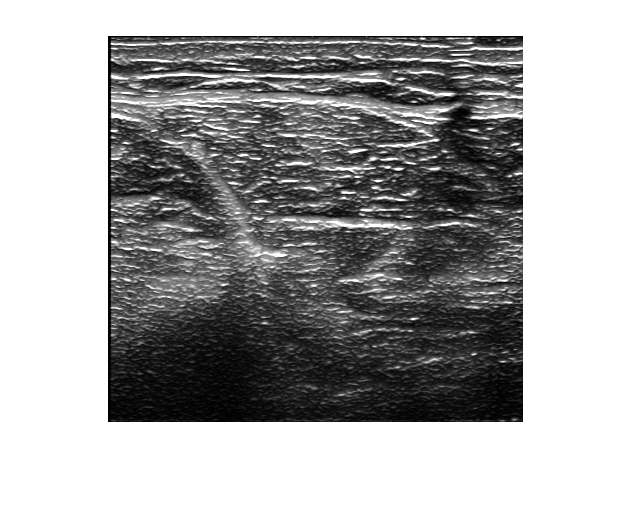

imshow(res_im)

emph_fas = 385×415 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

vol_swe(10,10,:,1)

volshow(vol_ny)